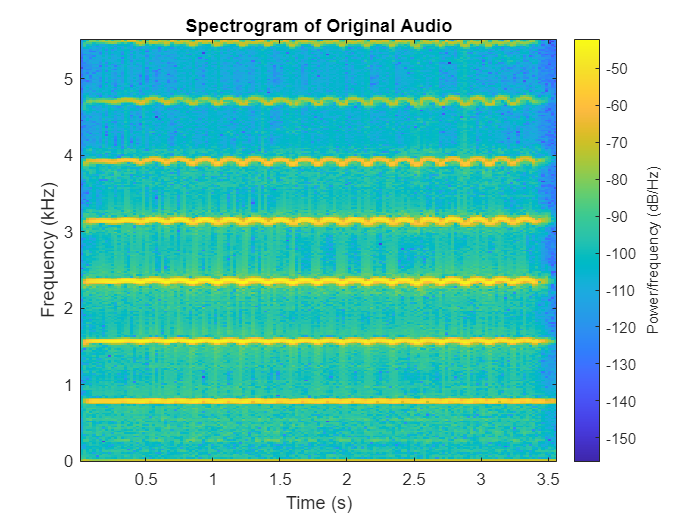

[y, Fs] = audioread('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-6\instru2.wav'); % Replace with your file path

figure;
spectrogram(y, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Original Audio');

% Butterworth band-pass filter
order = 10; % Filter order
Fc1 = 500; % Lower cutoff frequency in Hz 
Fc2 = 3000; % Upper cutoff frequency in Hz

% Normalize cutoff frequencies
Wn1 = Fc1 / (Fs/2);
Wn2 = Fc2 / (Fs/2);

% Design the filter
[b, a] = butter(order, [Wn1, Wn2], 'bandpass');

% Apply the filter to the audio signal
filtered_signal = filter(b, a, y);

% Write the filtered signal to a new WAV file
audiowrite('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-6\filtered_audio.wav', filtered_signal, Fs);

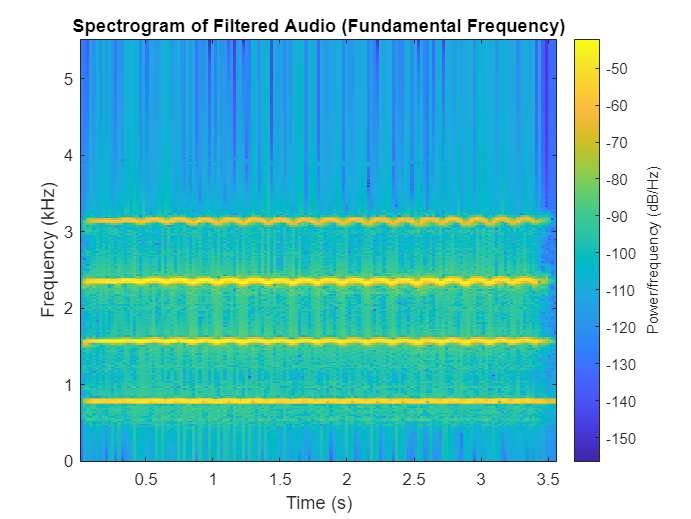

figure;
spectrogram(filtered_signal, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Filtered Audio (Fundamental Frequency)');